A = [5 2 0 ; 2 5 0; -3 4 6] % Generate the matrix A

A =      5     2     0
     2     5     0
    -3     4     6


[V, D] = eig(A); % Diagonalize
[V, D]

ans =          0    0.5774    0.3665    6.0000         0         0
         0    0.5774   -0.3665         0    7.0000         0
    1.0000    0.5774    0.8552         0         0    3.0000


[D, I] = sort(diag(D), 'descend'); % Sort eigenvalues
V = V(:, I); % Change order of eigenvectors properly
x1 = V(:,1); x2 = V(:,2); x3 = V(:,3); % Retrieve eigenvectors
lambda1 = D(1); lambda2 = D(2); lambda3 = D(3); % Retrieve eigenvalues

v0 = rand(3,1) % Generate a random starting vector

v0 =     0.9502
    0.0344
    0.4387


v0 = v0 - ((v0'*x1)*x1)/norm(x1) % Remove projection from eigenvector x1

v0 =     0.4758
   -0.4400
   -0.0357


a1_0 = v0'*x1 % Check that a1=0 (up to floating-point errors)

a1_0 = -5.5511e-17


v1 = 0.5*x2 + 0.7*x3;
a1_1 = v1'*x1

a1_1 = 0.6343


N=100

N = 100

for i=1:N
    v0 = A*v0;
    v0 = v0 / norm(v0);
end

v0

v0 =     0.5774
    0.5774
    0.5773


x1

x1 =     0.5774
    0.5774
    0.5774


x2

x2 =      0
     0
     1


x3

x3 =     0.3665
   -0.3665
    0.8552


New try

clear variables;

eigval = [5,4,3,2,1]; % Create diagonal matrix
X = rand(5,5);
Xo = orth(X);
for n=1:5
    X(:,n) = X(:,n)/norm(X(:,n)); % Normalize columns (eigenvectors)
    Xo(:,n) = Xo(:,n)/norm(Xo(:,n)); 
end


Xinv=inv(X); Xoinv=inv(Xo); % X may not be invertible; in that case run again
A = X*diag(eigval)*Xinv; % Matrix with eigvalues 5,4,3,2,1
Ao = Xo*diag(eigval)*Xoinv;


x1=X(:,1); x2=X(:,2); % Retrieve first two eigenvectors
x1 = x1/norm(x1); x2 = x2/norm(x2);
x1o=Xo(:,1); x2o=Xo(:,2);

y = rand(5,1); % Generate random starting vector
%y = y-((y'*x1)*x1)/(norm(x1)^2); % Remove projection from eigenvector x1
proj = Xinv*y;
y = y - proj(1)*Xinv(1,:);

y = y/norm(y);
%%%y = y - ((y'*Xinv(1,:)')*Xinv(1,:)'/norm(Xinv(1,:))^2)
a_1 = y'*x1 % Check that a1=0 (up to floating-point errors)

a_1 =    -0.0796
    0.4299
    0.6362
   -0.2442
    0.2686


a_2 = y'*x2;
Xinv*y

ans =    -0.1241   -0.1417   -0.1488   -0.1185   -0.1361
   -0.3263   -0.0890    0.0072   -0.4030   -0.1641
    0.0608    0.1713    0.2161    0.0251    0.1364
    0.1453    0.2644    0.3126    0.1068    0.2267
    0.1965    0.3494    0.4114    0.1471    0.3010




z = rand(5,1); z = z/norm(z);
z = z-((z'*x1o)*x1o)/(norm(x1o)^2);
b_1 = z'*x1o % Check that a1=0 (up to floating-point errors)

b_1 = 1.8041e-16

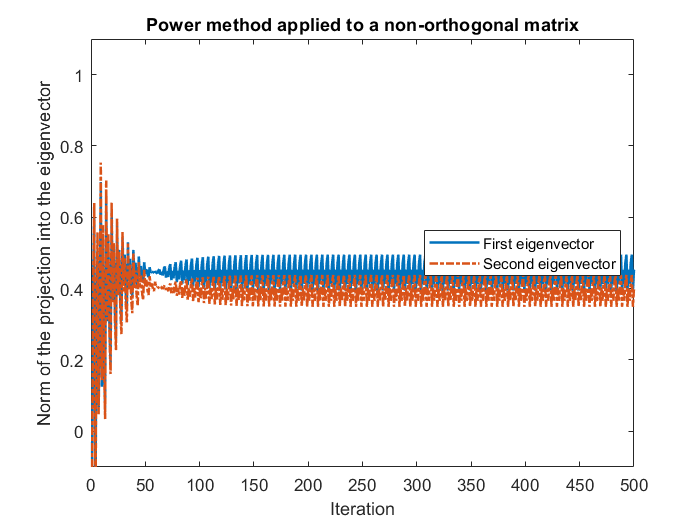

b_2 = z'*x2o;

A_1=[a_1]; A_2=[a_2]; % Array containing the projections of y into x1 and x2
B_1=[b_1]; B_2=[b_2]; %                  ""                 z      x1o    x2o 

N=500;
for i=1:N
    y = A*y; y = y/norm(y);
    A_1 = [A_1; abs(y'*x1)];
    A_2 = [A_2; abs(y'*x2)];
    
    z = Ao*z; z = z/norm(z);
    B_1 = [B_1; abs(z'*x1o)];
    B_2 = [B_2; abs(z'*x2o)];
end

figure(1)
axes('xlim', [0, N], 'ylim', [-0.1, 1.1])
box on
hold on;
plot(A_1, "LineWidth", 1.5)
plot(A_2, "-.", "LineWidth", 1.5)
legend("First eigenvector", "Second eigenvector", 'Location', "east")
xlabel("Iteration")
ylabel("Norm of the projection into the eigenvector")
title("Power method applied to a non-orthogonal matrix")

hold off;

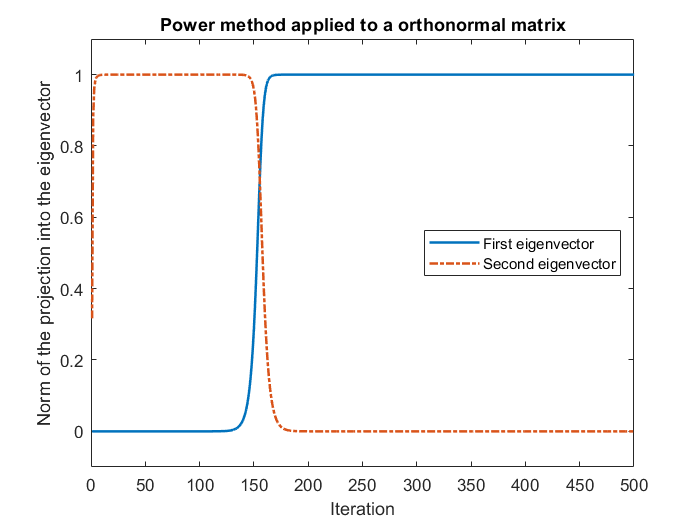


figure(2)
axes('xlim', [0, N], 'ylim', [-0.1, 1.1])
box on;
hold on;
plot(B_1, "LineWidth", 1.5)
plot(B_2, "-.", "LineWidth", 1.5)
legend("First eigenvector", "Second eigenvector", 'Location', "east")
xlabel("Iteration")
ylabel("Norm of the projection into the eigenvector")
title("Power method applied to a orthonormal matrix")
hold off;